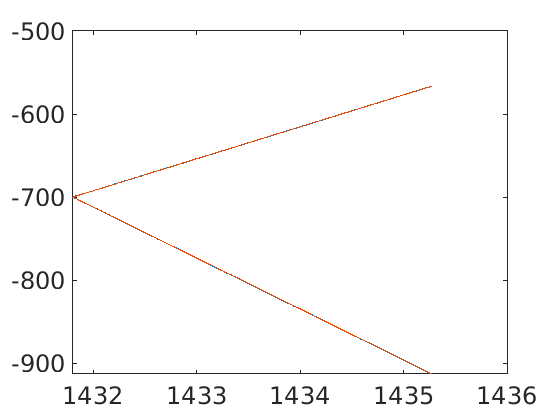

%question 1
close all;
clear all;
clc
%question 1
H = 3500;%max depth 3500m
zs = 600; %placement of sonar
dt = 0.005;
total_time = 15;
t = 0:dt:total_time;


theta01 = 2*pi/180;
theta02 = -2*pi/180;

x1 = zeros(size(t));
x2 = zeros(size(t));

z1 = zeros(size(t));
z2 = zeros(size(t));

theta1 = zeros(size(t));
theta2 = zeros(size(t));

c1 = zeros(size(t));
c2 = zeros(size(t));


x1(1) = 0;
x2(1) = 0;

z1(1) = zs;
z2(1) = zs;

theta1(1) = theta01;
theta2(1) = theta02;

c1(1) = velocity(z1(1));
c2(1) = velocity(z2(1));

snails_constant1 = cos(theta01)/c1(1);
snails_constant2 = cos(theta02)/c2(1);

for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));
    
    
    x2(i) = x2(i-1) + c2(i-1)*dt*cos(theta2(i-1));
    z2(i) = z2(i-1) + c2(i-1)*dt*sin(theta2(i-1));
    c2(i) = velocity(z2(i));
    
    
    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    if snails_constant2*c2(i) <= 1
        theta2(i) = sign(theta2(i-1))*acos(snails_constant2*c2(i));
    else
        z2(i) =z2(i-1) ;
        c2(i) = c2(i-2);
        theta2(i) = -theta2(i-2);
        
    end
    
    if z1(i) < 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    elseif z1(i)>H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    end
    
    if z2(i) < 0
        z2(i) =z2(i-1) ;
        c2(i) = c2(i-2);
        theta2(i) = -theta2(i-2);
    elseif z2(i)>H
        z2(i) =z2(i-1) ;
        c2(i) = c2(i-2);
        theta2(i) = -theta2(i-2);
    end
    
end


plot(c1,-z1)
hold on
plot(c2,-z2)

hold off

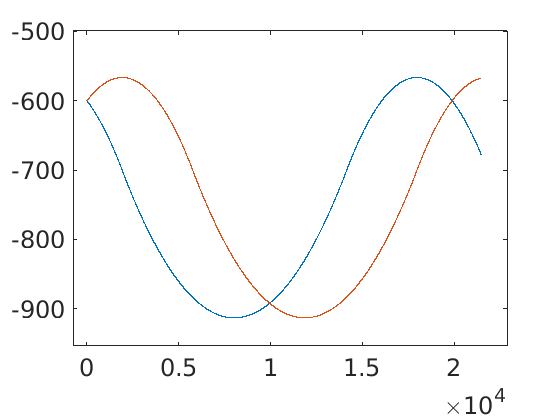

plot(x1,-z1)
hold on
plot(x2,-z2)
hold off


disp('max_depth: ')

max_depth: 


disp(max(max([z1;z2])))

  913.1490



%question 2
%question 1
close all;
clear all;
clc
%question 1
H = 3500;%max depth 3500m
zs = 600; %placement of sonar
dt = 0.0005;
total_time = 15;
t = 0:dt:total_time;


theta01 = 2*pi/180;

x1 = zeros(size(t));

z1 = zeros(size(t));

theta1 = zeros(size(t));

c1 = zeros(size(t));


x1(1) = 0;

z1(1) = zs;

theta1(1) = theta01;

c1(1) = velocity(z1(1));

snails_constant1 = cos(theta01)/c1(1);
our_ans = 0;
for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));

    if x1(i)>=10000 
        if (our_ans==0)
        our_ans = sprintf('the distance is %f and the depth is %f',x1(i), z1(i))
        end
    end
    
    
    
    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    
    if z1(i) < 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    elseif z1(i)>H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    end
    
    
end

our_ans = 'the distance is 10000.414126 and the depth is 891.186619'

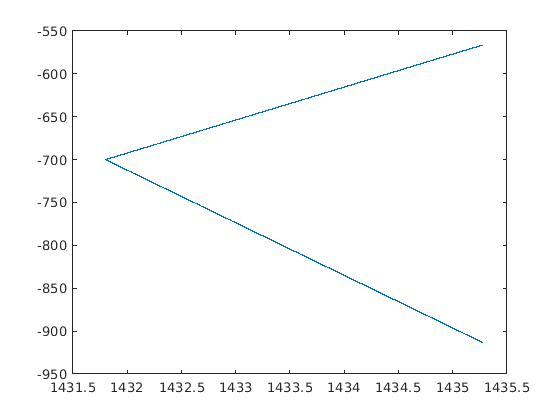



plot(c1,-z1)

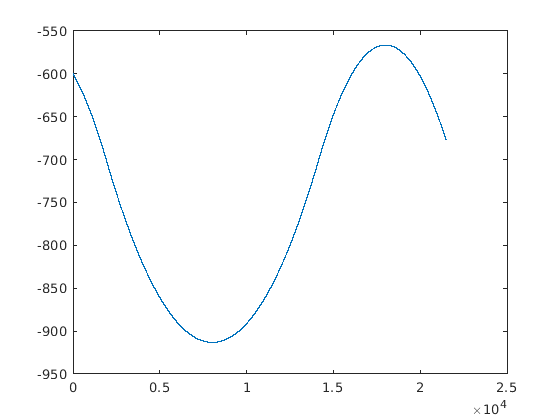


plot(x1,-z1)

function c= velocity(z,l,q)
    z2 = 700;
    c0 = 1450;
    
    m1 = -0.026;
    
    c2 = m1*z2 + c0;
    
    if z<z2
        c = m1*z + c0;
    
    elseif z>=z2
        m2 = 1.63*10^-2;
        c = m2*z + (c2 - m2*z2);
    end
    
end